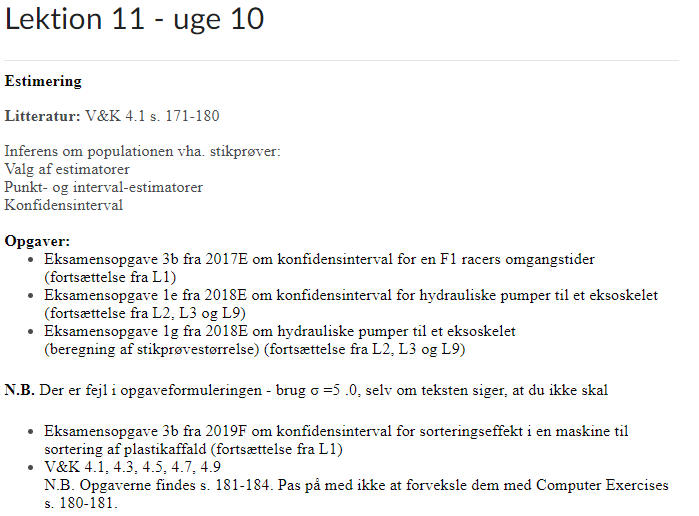

clc; clear all;

for i = 1:10
x(i) = randi(10)
end

x = 8

x =      8     3


x =      8     3     2


x =      8     3     2     3


x =      8     3     2     3     4


x =      8     3     2     3     4     5


x =      8     3     2     3     4     5     6


x =      8     3     2     3     4     5     6     1


x =      8     3     2     3     4     5     6     1     3


x =      8     3     2     3     4     5     6     1     3     9


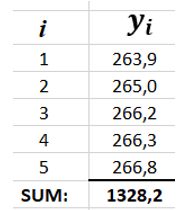

clc; clear all;

x = [263.9, 265, 266.2, 266.3, 266.8]

x =   263.9000  265.0000  266.2000  266.3000  266.8000



pd = fitdist(x',"Normal")

pd =   NormalDistribution

  Normal distribution
       mu =  265.64   [264.18, 267.1]
    sigma = 1.17601   [0.704587, 3.37933]




ki = paramci(pd, 'Alpha',0.05)

ki =   264.1798    0.7046
  267.1002    3.3793



-norminv(0.025)

ans = 1.9600



ki_mu = ki(:,1)

ki_mu =   264.1798
  267.1002


x = [-2 -1 0 1 2 3 4]

x =   -200  -100     0   100   200   300   400


Da populations-standardafvigelsen er ukendt, bruges følgende formel til at udregne konfidensintervallet


$$\bar{y}+\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

$$\bar{y}-\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

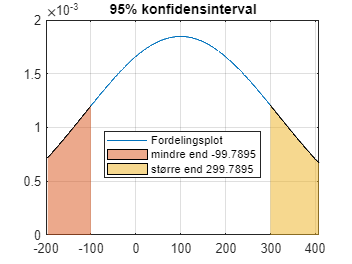

    Interval    Værdier
    ________    _______

    "Nedre"     -99.79 
    "Øvre"      299.79 



KonfidensIntervalNormal(x, 95, [])

xx = min(x)*0.98:0.1:max(x)*1.02;

lower = find(xx < ki_mu(1))

lower =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


upper = find(xx > ki_mu(2))

upper =     86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135



alpha1 = 1

alpha1 = 1


pd2 = pdf(pd,xx)

pd2 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0010    0.0013    0.0017    0.0023    0.0030    0.0039    0.0050    0.0063    0.0080    0.0101    0.0126    0.0156    0.0192    0.0235    0.0285    0.0343    0.0410    0.0486    0.0573    0.0670


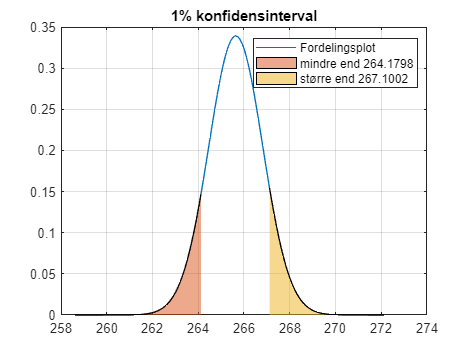


plot(xx, pd2, "DisplayName","Fordelingsplot"), grid()
hold on

area(xx(1:length(lower)), pd2(1:length(lower)), "DisplayName","mindre end "+ki_mu(1))
area(xx(upper(1):end), pd2(upper(1):end), "DisplayName","større end "+ki_mu(2))

alpha(0.5)
title(alpha1 + "% konfidensinterval")
legend('show', 'location','best')
hold off

$$ans = \mathrm{Sum}$$